# 2030 MATLAB coding exercises

Due date: Sunday 30/10/2022, 11:59 pm

**Your name**: Gabriel Katzeff    

**Your student number**: 45870853

**Your email address**: gabriel.katzeff@students.mq.edu.au

## Description

In this `.mlx` file, i.e., `codingProblems.mlx`, there are 15 MATLAB programming exercises for you to attempt and all have the same mark. This assignment contributes %15 to the total course assessment.

## Instructions 

Please:

- Download all the files in the folder posted on iLearn and save them in one folder.

- Do not remove section breaks in this file.

- Do not change the order of the exercises.

- Use the code boxes provided in this file to write your scripts for each section/subsection.

- Note that there are also a few questions for you to answer. You need to type your answers in the file next to "**Your answer to part ...**".

- Use comments when writing your MATLAB scripts.

- Use the function `plotSpectrum()` for finding and plotting spectrums and `filtDesign()` for designing filters.

- When plotting, use appropriate labels for x- and y- axes and sutible titles for the figures. Also, use `figure` command before creating a new figure. Use `sgtitle()` where appropriate.

**Important note:** Once done, you need to submit only the completed `.mlx` file with the outputs.

Good luck!

## Exercise 1

Write a MATLAB script to execute the following steps:

    **a)** clear MATLAB worksapce

    **b)** declare the variables $a$ and $b$ as follows:


$$\begin{array}{l}
a=\frac{\left(2-3i\right)}{\sqrt{5}}{\left(\frac{-3}{5}\right)}^3 \\
b={\left(3\sqrt{7}-\frac{3}{4}\right)}^2 +\frac{\pi \;}{6}
\end{array}$$
 

% script for parts a) and b)
clear
clc

% Declaring variable a
a = ((2-3*1i)/sqrt(5))*(-3/5)^3;
% Declaring variable b
b = (3*sqrt(7)-3/4)^2+pi/6;

    **c)** evaluate the results of the following expressions:


$$\begin{array}{l}
c=a^3 +2b\\
d=a\sqrt{c+\textrm{ab}}
\end{array}$$


% script for part c)
c = a^3 + 2*b;
d = a*sqrt(c+a*b);

   ** d)** use *who* and *whos* commands to display the list of the variables currently in the memory and their details.

    **e)** save  the result in the file `exercise1Results.mat`.

% script for parts c) and d)
who


Your variables are:

a  b  c  d  



whos

  Name      Size            Bytes  Class     Attributes

  a         1x1                16  double    complex   
  b         1x1                 8  double              
  c         1x1                16  double    complex   
  d         1x1                16  double    complex   



save('excercise1Results.mat');

## Exercise 2

    **a) **Generate the following matrices:


$$\mathrm{A}=\left\lbrack \begin{array}{cccc}
1 & -2 & 4 & 0\\
-3 & 6 & -3 & 4\\
8 & -1 & 3 & 2\\
5 & -7 & 8 & -2
\end{array}\right\rbrack ,\mathrm{B}=\left\lbrack \begin{array}{cccc}
0 & -2 & 6 & 3\\
9 & 1 & -4 & 7\\
2 & -3 & 0 & -1\\
5 & -8 & 0 & -3
\end{array}\right\rbrack$$


% script for part a)
% Matrix A
clear
A = [1 -2 4 0; -3 6 -3 4; 8 -1 3 2; 5 -7 8 -2];
% Matrix B
B = [0 -2 6 3; 9 1 -4 7; 2 -3 0 -1; 5 -8 0 -3];

    **b) **Delete the 4th column of A and the 3rd row of B. Rename the new matrices C and D, respectively.

% script for part b)
% Matrix C
C = A(:,1:3);
% Matrix D
D = B([1 2 4],:);

    **c) **Multiply and divide the matrices C and D', i.e., transpose of D, element-by-element.

% script for part c)
% transposing D
D_trns = D';
% Multiplying C and D'
C.*D_trns; % Using element by element multiplication
% Dividing C by D
C./D_trns; % Using element by element multiplication

    **d) **Interchange rows 1 and 3 of A and interchange columns 2 and 4 of B.

% script for part d)
A_inter = A([3 2 1 4],:); % recreating A in order of rows 3,2,1,4 with all columns selected
B_inter = B(:,[1 4 3 2]); % recreating B in order of columns 1,4,3,2 with all rows selected

## **Exercise 3**

    **a)** Create the time vector `t `consisting of points (0,0.01,0.02,0.03,··· ,3).

    **b)** Generate samples of the following mathematical expression.


$$x(t) = \sqrt{2t}  e^{-\pi t} \cos(2\pi10t+\pi/2)$$


    **c)** Plot the signal generated in part **b)** as a function of $t$.

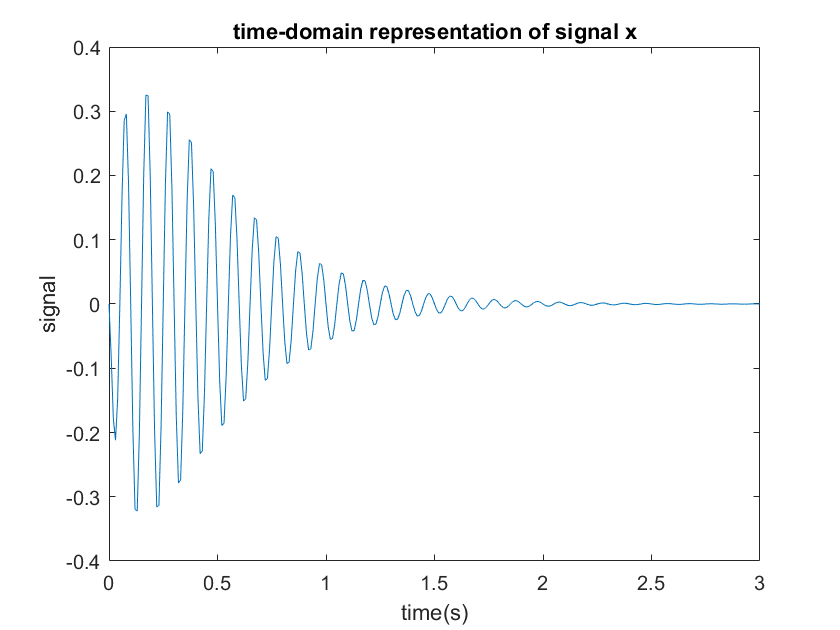

% scripts for parts a), b), and c)
clc
clear
% a)
t = 0:0.01:3; % iterating by .01
% b)
x = sqrt(2*t).*exp(-pi*t).*cos(2*pi*10*t+pi/2);
%plot
figure;
plot(t,x); xlabel('time(s)'); ylabel('signal'), title('time-domain representation of signal x');

## **Exercise 4**

    **a) **Use `whos` to check variables saved in `handel.mat `file.

    **b) **Load the file and display the sampling rate (in Hz) and the duration of the signal (in s) using `disp()`.

% script for parts a) and b)
clc
clear
% a)
whos -file handel.mat

  Name          Size             Bytes  Class     Attributes

  Fs            1x1                  8  double              
  y         73113x1             584904  double              



% b)
load handel.mat
filename = 'handel.wav';
audiowrite(filename,y,Fs); % create a .wav file
clear y Fs
[y,Fs] = audioread('handel.wav');
% displaying sampling rate in Hz
disp(['The sampling rate of the signal handel.wav is Fs=' , num2str(Fs), ' Hz'])

The sampling rate of the signal handel.wav is Fs=8192 Hz


% displaying signal duration in seconds
disp(['The duration of the signal handel.wav is: ' , num2str((length(y)-1)/Fs) , ' s'])% duration not length

The duration of the signal handel.wav is: 8.9248 s


    **c) **Plot the signal using` plot()`.

    **d) **Play the signal using `sound()`.

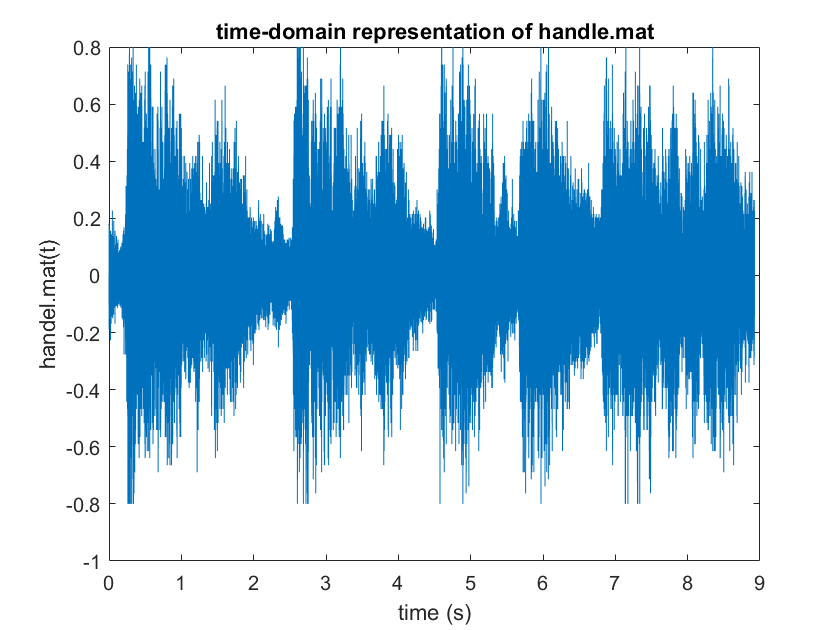

% script for parts c) and  d)
% c)
t = (0:length(y)-1)/Fs; % generate the time vector
figure;
plot(t,y); xlabel('time (s)'), ylabel('handel.mat(t)'), title('time-domain representation of handle.mat')

% d)
sound(y,Fs) % Playing the signal
pause(10);

    **e) **Generate a random vector using `randn()` with the same number of samples as the audio signal.

    **f) **Add the random sequence to the audio signal and play it.

% script for parts e) and  f)
% e) 
randvec = randn(length(y),1); % length(y) ensures randvec has the same number of samples as y, (,1) ensures that randvec is row vector with 1 column, same as y. 
ynoisy = y+randvec; % Combining the signals
% Playing the combined signals
sound(ynoisy,Fs);

## **Exercise 5**

    **a)** Generate samples of the following 4 waves in the interval $-2\pi \le x\le 2\pi \;$. Use the sampling rate $f_s = 10$ Hz. 


$$\begin{array}{l}
y_1 =-1\ldotp 5\;\sin \left(x\right)\\
y_{2\;} =2\;\sin \left(x+\frac{\pi }{3}\right)\\
y_3 =-3\;\sin \left(x-\frac{\pi }{5\;}\right)\\
y_{4\;} =1\ldotp 5\;\sin \left(x+\frac{2\pi }{3\;}\right)
\end{array}$$


% script for part a)
Fs = 10; % Sampling rate = 10 Hz
x = -2*pi:1/Fs:2*pi; % generating x vector
y1 = 1.5.*sin(x); % sinusoid 1
y2 = 2.*sin(x+pi/3); % sinusoid 2
y3 = -3.*sin(x-pi/5); % sinusoid 3
y4 = 1.5.*sin(x+(2*pi)/3); % sinusoid 4

**    b)** Plot the waves in the same figure using different line-styles, colors, and markers. Add legend as well. 

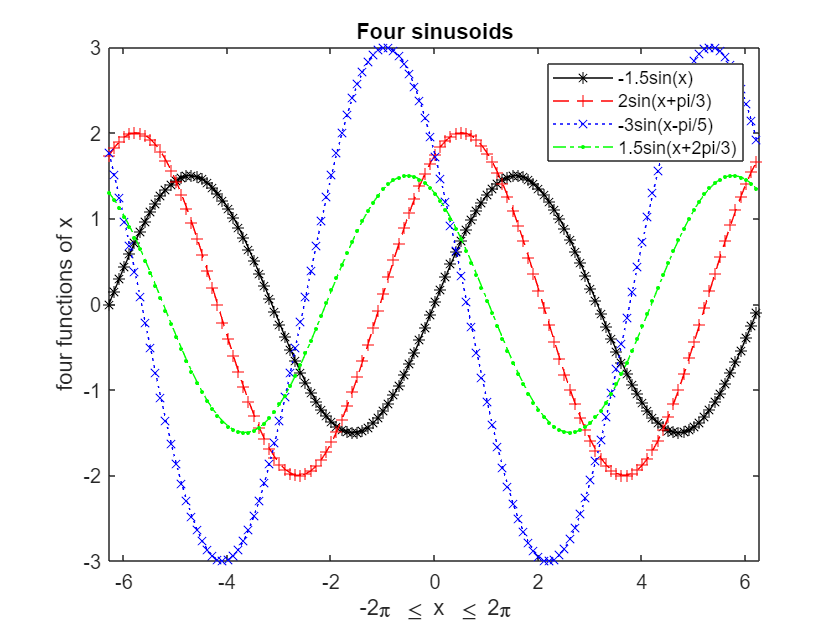

% script for part b)
figure;
plot(x,y1,'k-*',x, y2,'r--+',x,y3, 'b:x',x,y4, 'g-..') % plots sinusoid 1 with black colour (k), straight line-style '-', and '*' markers, 
% sinusoid 2 with red colour, broken line-style '- -', and '+' line marker
% sinusoid 3 with blue colour, dotted line-style ':', and 'x' line marker
% sinusoid 4 with green colour, '-.' line-style, and '.' line marker
xlabel('-2\pi \leq x \leq 2\pi') % sets the xlabel to the x vector limits 
ylabel('four functions of x')
title('Four sinusoids')
legend('-1.5sin(x)', '2sin(x+pi/3)', '-3sin(x-pi/5)', '1.5sin(x+2pi/3)') % creates a legend for the sinusoids
axis([-2*pi 2*pi -3 3]) % Limits the width of the graph to the x limits of the sinusoids for better view.

    **c)** Plot the functions in 4 rows using `subplot()`.

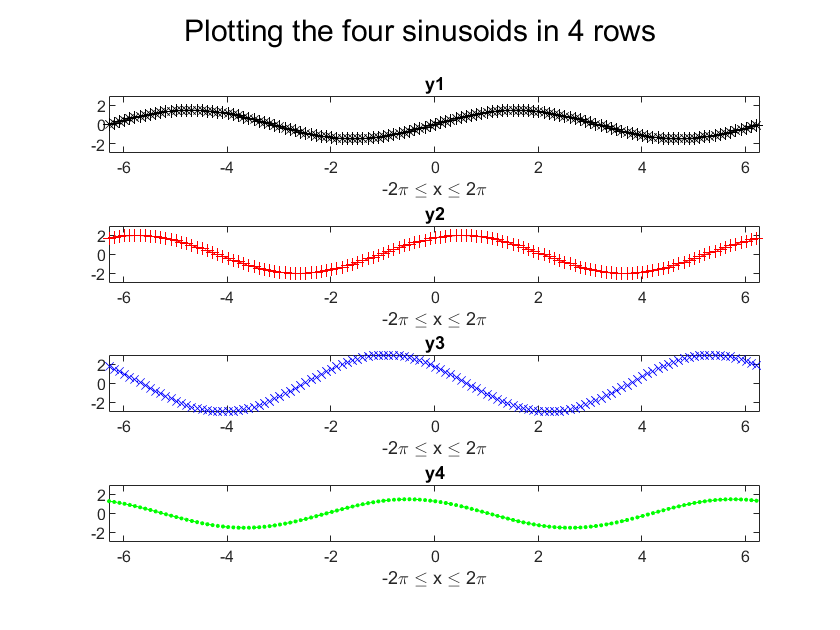

% script for part c)
figure;
subplot(411), plot(x,y1,'k-*'), title('y1'), xlabel('-2\pi \leq x \leq 2\pi'), axis([-2*pi 2*pi -3 3])
subplot(412), plot(x, y2,'r--+'), title('y2'), xlabel('-2\pi \leq x \leq 2\pi'), axis([-2*pi 2*pi -3 3])
subplot(413), plot(x,y3, 'b:x'), title('y3'),  xlabel('-2\pi \leq x \leq 2\pi'), axis([-2*pi 2*pi -3 3])
subplot(414), plot(x,y4, 'g-..'), title('y4'), xlabel('-2\pi \leq x \leq 2\pi'), axis([-2*pi 2*pi -3 3])
sgtitle('Plotting the four sinusoids in 4 rows');

**    d) **Plot the functions in 2 rows and 2 columns using `subplot()`. 

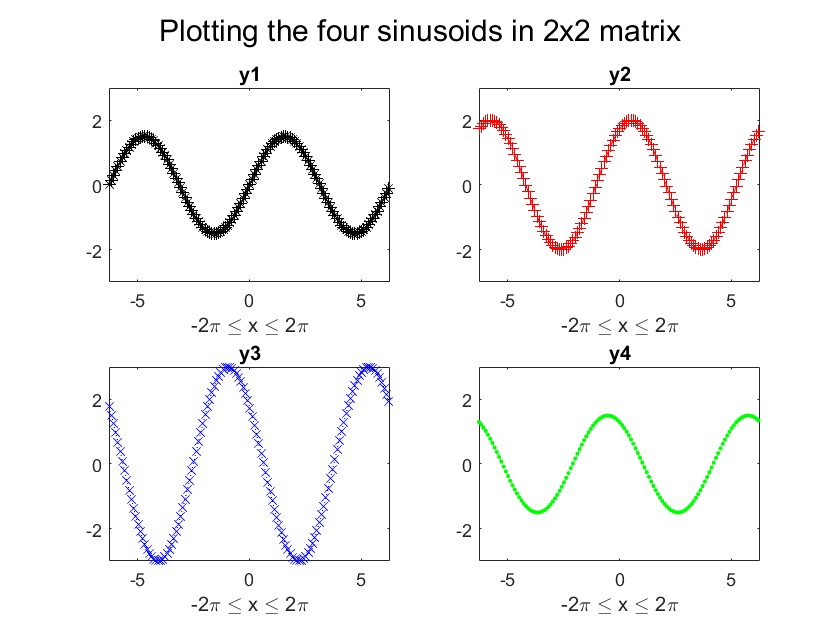

% script for part d)
figure;
subplot(221), plot(x,y1,'k-*'), title('y1'), xlabel('-2\pi \leq x \leq 2\pi'), axis([-2*pi 2*pi -3 3])
subplot(222), plot(x, y2,'r--+'), title('y2'), xlabel('-2\pi \leq x \leq 2\pi'), axis([-2*pi 2*pi -3 3])
subplot(223), plot(x,y3, 'b:x'), title('y3'),  xlabel('-2\pi \leq x \leq 2\pi'), axis([-2*pi 2*pi -3 3])
subplot(224), plot(x,y4, 'g-..'), title('y4'), xlabel('-2\pi \leq x \leq 2\pi'), axis([-2*pi 2*pi -3 3])
sgtitle('Plotting the four sinusoids in 2x2 matrix');

## **Exercise 6**

**    a)** Generate the following waveforms in the time interval $0 \leq t \leq 3$. Use the sampling frequency $f_s = 400 $ Hz.

         
$$x_1(t) = \frac 12 -\frac 1 \pi \sin\left(4\pi t \right) \\
x_2(t) =  -\frac 1 {2\pi} \sin\left(8\pi t \right)  \\
x_3(t) =  -\frac 1{3\pi} \sin\left(12\pi t \right) \\
x_4(t) =  -\frac 1{4\pi} \sin\left(16\pi t \right) \\
x(t) = x_1(t) + x_2(t) + x_3(t) + x_4(t) $$


% script for part a)
clear
Fs = 400; % Sets sampling freq
t = 0:1/Fs:3; % time vector according to 0<=t<=3
x1 = 1/2-(1/pi).*sin(4*pi*t);
x2 = -1/(2*pi).*sin(8*pi*t);
x3 = -1/(3*pi).*sin(12*pi*t);
x4 = -1/(4*pi).*sin(16*pi*t);
x = x1+x2+x3+x4; % Combined waveform

    **b)** Plot the signals $x_1(t), x_2(t), x_3(t), x_4(t)$and $x(t)$in the time interval $0 \leq t \leq 1$ in 3 rows and 2 columns using `subplot()`.

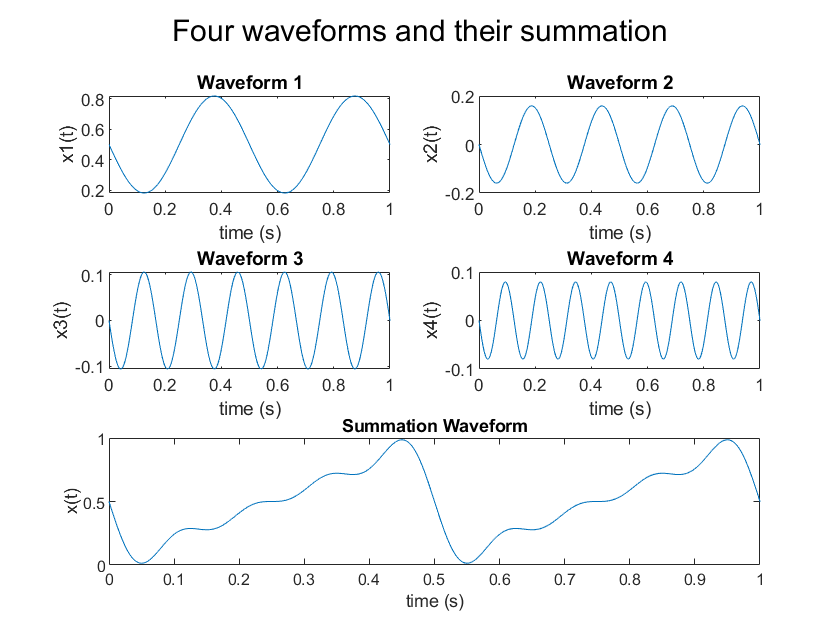

% script for part b)
figure;
subplot(321), plot(t,x1); xlim([0 1]); xlabel('time (s)'), ylabel('x1(t)'), title('Waveform 1');
subplot(322), plot(t,x2); xlim([0 1]); xlabel('time (s)'), ylabel('x2(t)'), title('Waveform 2');
subplot(323), plot(t,x3); xlim([0 1]); xlabel('time (s)'), ylabel('x3(t)'), title('Waveform 3');
subplot(324), plot(t,x4); xlim([0 1]); xlabel('time (s)'), ylabel('x4(t)'), title('Waveform 4');
subplot(3,2,[5 6]), plot(t,x); xlim([0 1]); xlabel('time (s)'), ylabel('x(t)'), title('Summation Waveform');
sgtitle('Four waveforms and their summation')

    **c)** What type of signal does $x(t)$ represent? Identify the period and frequency of the signal $x(t)$.

    **Your answer to part c)**: 

Sawtooth, period = 0.5, frequency = 2. 

    **d)** Plot the spectrum of the signals $x_1(t), x_2(t), x_3(t), x_4(t)$and $x(t)$ using `plotSpectrum()`. Use `subplot()` to plot the spectrums in 3 rows and 2 columns.

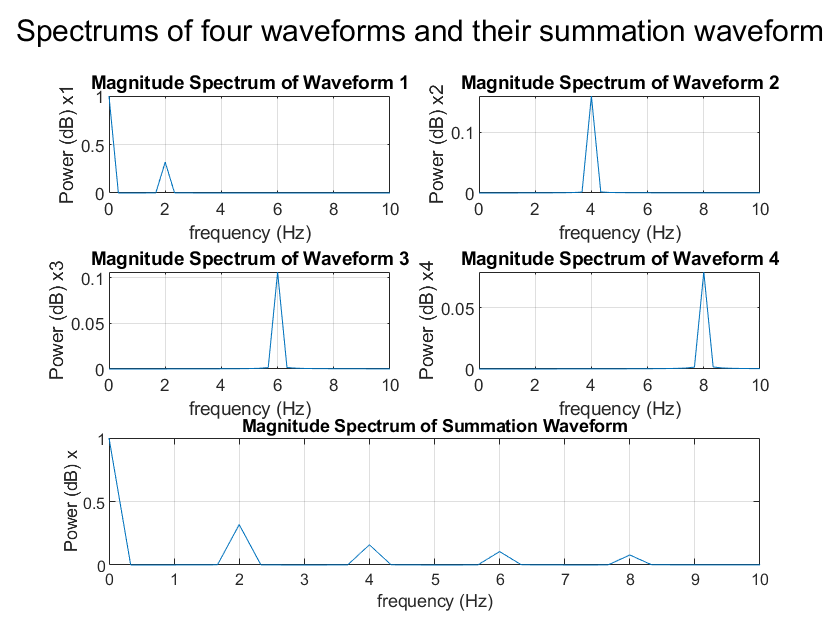

% script for part d)
figure
subplot(321), plotSpectrum(x1,Fs); xlim([0 10]); ylabel('Power (dB) x1'); title('Magnitude Spectrum of Waveform 1');
subplot(322), plotSpectrum(x2,Fs); xlim([0 10]); ylabel('Power (dB) x2'); title('Magnitude Spectrum of Waveform 2');
subplot(323), plotSpectrum(x3,Fs); xlim([0 10]); ylabel('Power (dB) x3'); title('Magnitude Spectrum of Waveform 3'); 
subplot(324), plotSpectrum(x4,Fs); xlim([0 10]); ylabel('Power (dB) x4'); title('Magnitude Spectrum of Waveform 4');
subplot(3,2,[5 6]), plotSpectrum(x,Fs); xlim([0 10]); ylabel('Power (dB) x'); title('Magnitude Spectrum of Summation Waveform');
sgtitle('Spectrums of four waveforms and their summation waveform');

    **e)** Use MATLAB `sawtooth()` function to generate a periodic sawtooth wave with period 0.5 s.

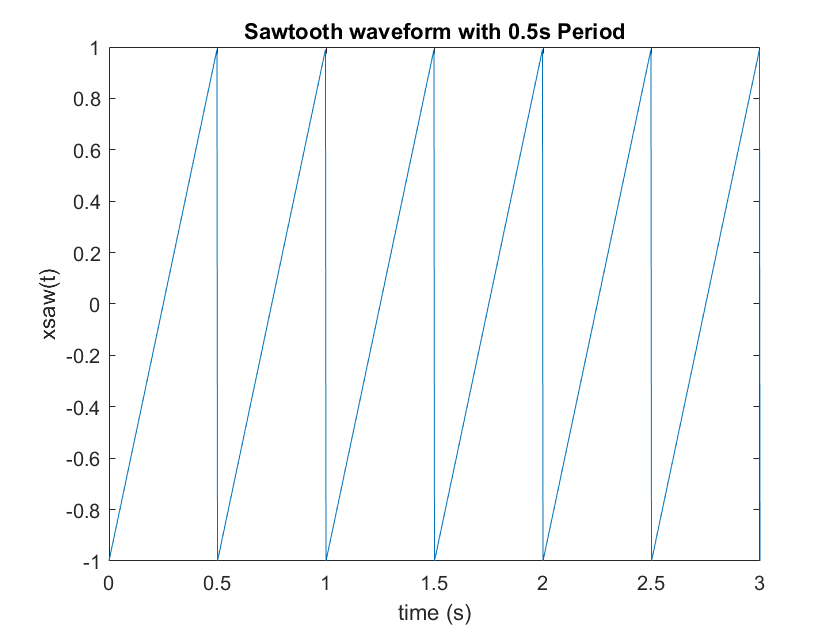

% script for part e)
xsaw = sawtooth(4*pi*t); % The original summation waveform was a sawtooth with period of 0.5, so we convert this to be used in sawtooth function with 4pi*t
figure;
plot(t,xsaw); xlabel('time (s)'), ylabel('xsaw(t)'); title('Sawtooth waveform with 0.5s Period');

    **f)** compare the results of parts **c)** and **d)**.

    **Your answer to part f)**: 

In c), the sinusoids of x1, x2, x3, and x4 are all represented in the time-domain signal of x, resulting in a sawtooth wave with periodicity of 0.5 and frequency of 2.

In d) the frequency-domain representation displays the fundamental frequency of x at 2 (judged by having the lowest frequency and highest amplitude), and the harmonics at frequencies 4, 6, and 8 Hz. 

## **Exercise 7 **

    **a) **Read the audio signal saved in `speech_dft.wav `file.

    **b) **Use `disp()` to display the number of channels, the sampling rate and the number of samples of the signal.

% script for parts a) and b)
[y, Fs] = audioread('speech_dft.wav'); % Reading in the file to  declar y and Fs
disp(['speech_dft.wav has ' , num2str(size(y,2)) , ' channels'])

speech_dft.wav has 1 channels


disp(['The vector y contains ' , num2str(length(y)) , ' samples'])

The vector y contains 110033 samples


disp(['The sampling rate of speech_dft.wav is Fs=' , num2str(Fs), ' Hz'])

The sampling rate of speech_dft.wav is Fs=22050 Hz


    **c) **Play the signal at the original sampling rate and also at twice the original rate.

% script for part c)
soundsc(y,Fs); 
pause(7)
soundsc(y,Fs*2); 

## **Exercise 8**

    **a) **Create a 20 s block recording (using your own voice for example).

% script for part a)
clear
Fs = 44100; % defining the sampling rate for the signal to be recorded
noChannels = 2; % to have stereo audio
noBits = 8;
recorder = audiorecorder(Fs, noBits, noChannels);
get(recorder) % displays the properties of the object

       SampleRate: 44100
    BitsPerSample: 8
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'



disp('start speaking')

start speaking


recordblocking(recorder, 20);
disp('End of recording')

End of recording


pause(3)

    **b) **Repeat the steps presented in **Example 7 in Tutorial_5.mlx** and save your recording in the `exercise8Recording.wav`.

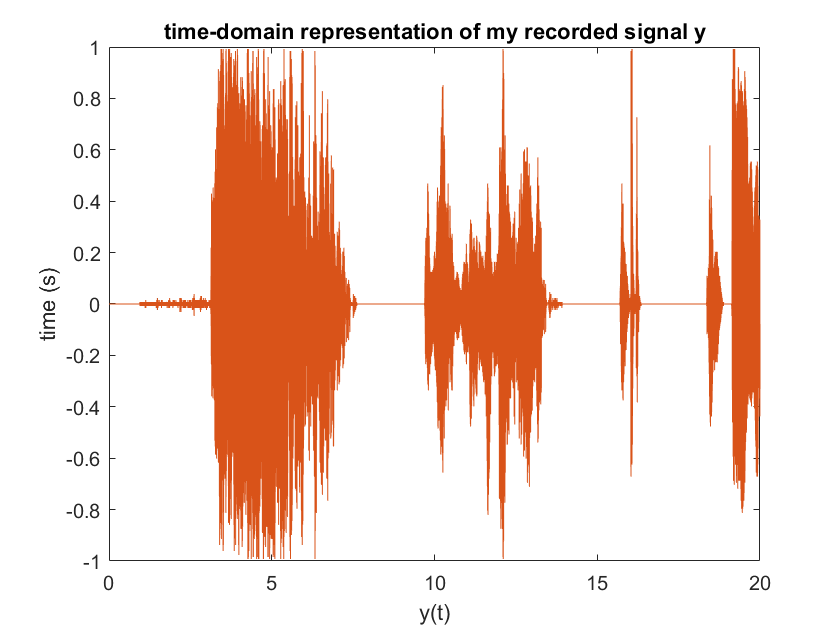

% script for part b)
play(recorder);
pause(20);
% storing data in a double precision array
y = getaudiodata(recorder);
t = (0:length(y)-1)/Fs;
figure
plot(t,y); ylabel('time (s)'), xlabel('y(t)'), title('time-domain representation of my recorded signal y');

audiowrite('excercise8Recording.wav', y, Fs); % Saves the recording

    **c) **Repeat the steps presented in **Example 6 in Tutorial_5.mlx **but for the recorded signal in part **b)**.

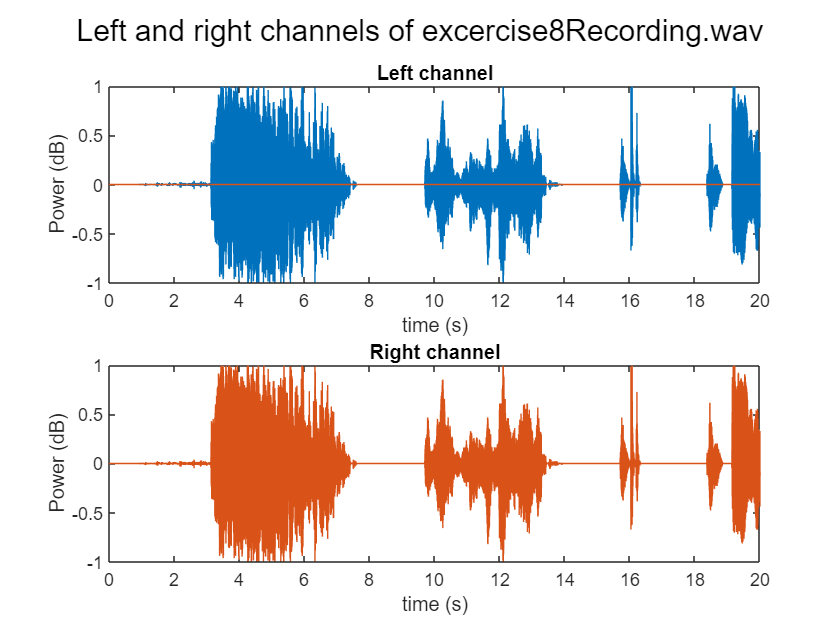

% script for part c)
[y, Fs] = audioread('excercise8Recording.wav'); % Declars y and Fs
y_left = y; % Creates left array channel
y_left(:,2) = 0; % setting the right column to 0, isolating left audio
y_right = y; % Creates right array
y_right(:,1)= 0; % setting left to 0, isolating right.
sound(y_left, Fs); % playing the left mono channel
pause(20);
sound(y_right,Fs); % playing the right mono channel
figure
subplot(211); plot(t,y_left);xlabel('time (s)');ylabel('Power (dB)');title('Left channel');
subplot(212), plot(t,y_right); xlabel('time (s)');ylabel('Power (dB)');title('Right channel');
sgtitle('Left and right channels of excercise8Recording.wav')

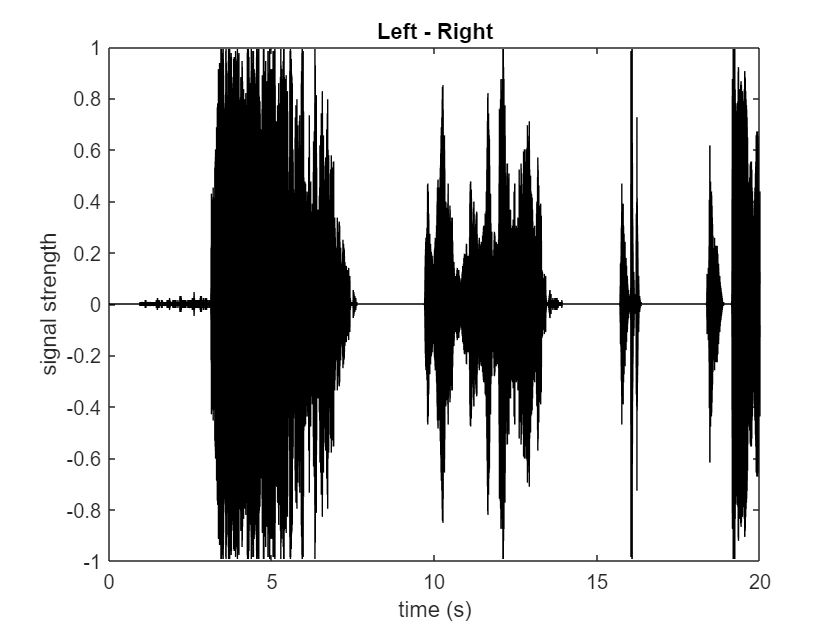

%subtracting the left from the right channel to get the difference between
y_left_minus_right = y_left - y_right;

figure;
plot(t,y_left_minus_right, 'k');xlabel('time (s)');ylabel('signal strength');title('Left - Right');

## **Exercise 9**

Consider the following signal. 


$$x{\left(t\right)}=\cos {\left(2\pi 50t\right)}+2\cos {\left(2\pi 200t\right)}+3\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi 500t\right)\;\;\;0\le t\le 0\ldotp 1\;s$$
      

    **a)** Choose the sampling rate of 5000 Hz and generate samples of the signal in the given time interval.

% script for part a)
clear
clc
Fs = 5000; % choosing 5000Hz sampling rate
t = 0:1/Fs:0.1; % generating time points
x = cos(2*pi*50*t)+2.*cos(2*pi*200*t)+3.*cos(2*pi*500*t); % generating signals of x(t)

   ** b)** Find the spectrum of the signal using `plotSpectrum()`. 

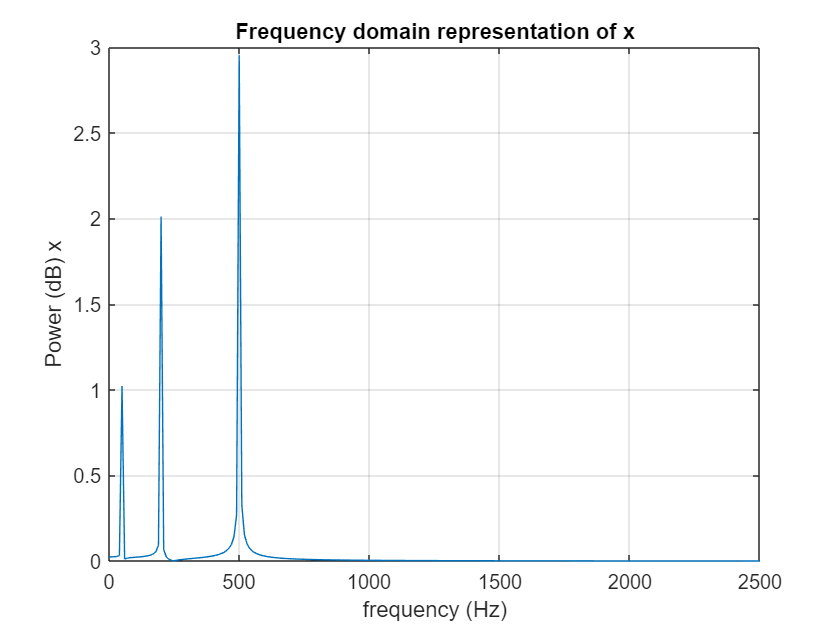

% script for part b)
figure;
plotSpectrum(x, Fs); ylabel('Power (dB) x'), title('Frequency domain representation of x')

    **c)** Repeat **Example 2** **in Tutorial_6.mlx** for the signal. When adding noise, use `noiseAmp = 10` and `noiseAmp = 0.1`.

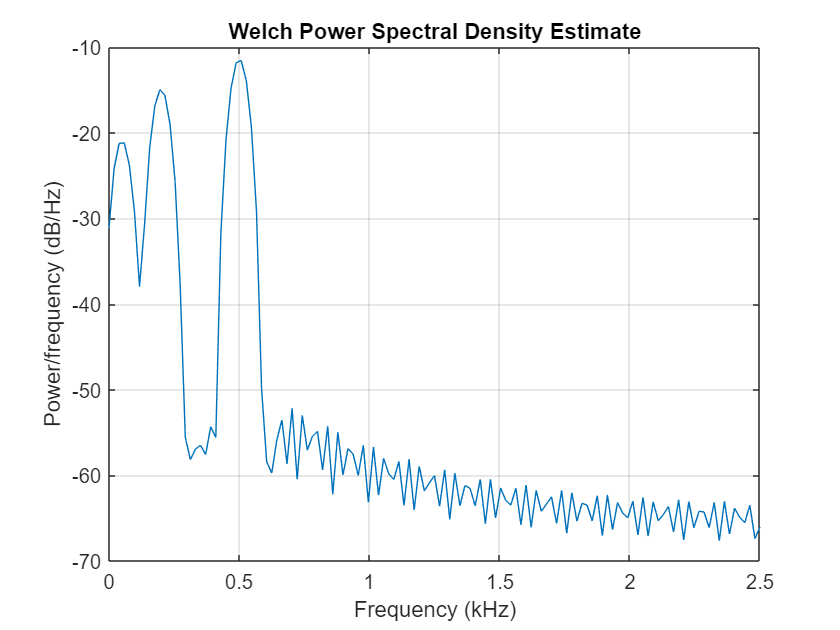

% script for part c)
figure
pwelch(x, [], [], [], Fs); % shows the Power Spectral Density (PSD) of x

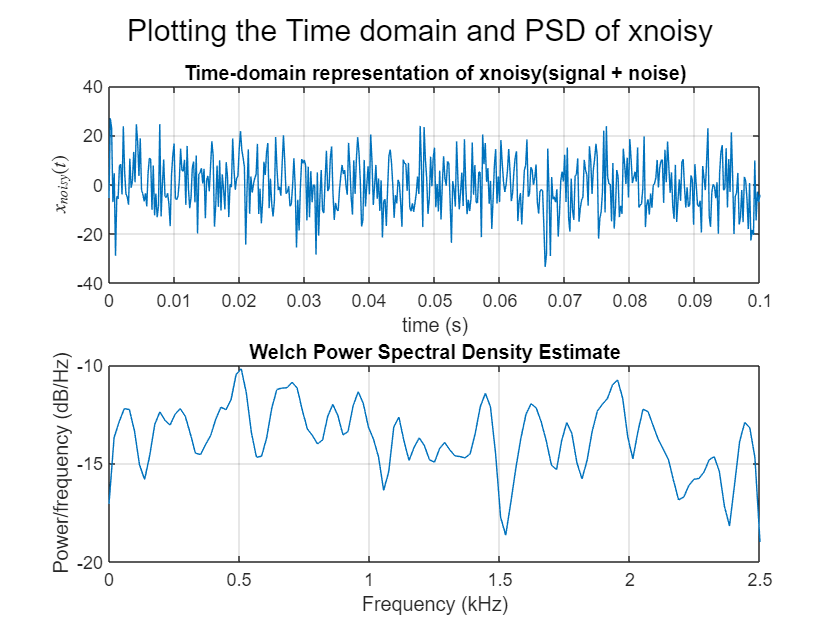

noiseAmp = 10; 
noise = noiseAmp*randn(size(t)); % creating random gaussian (normal) signal of same duration (t) as x but amplified *10
xnoisy = x + noise; % Adding the two to create a noisy signal
figure
subplot(211); plot(t,xnoisy); % Shows time-domain representation of xnoisy
grid on 
xlabel('time (s)');
ylabel('$x_{noisy}(t)$', 'Interpreter', 'latex');
title('Time-domain representation of xnoisy(signal + noise)');
subplot(212); pwelch(xnoisy,[],[],[],Fs) % Shows Power Spectral Density of xnoisy
sgtitle('Plotting the Time domain and PSD of xnoisy')

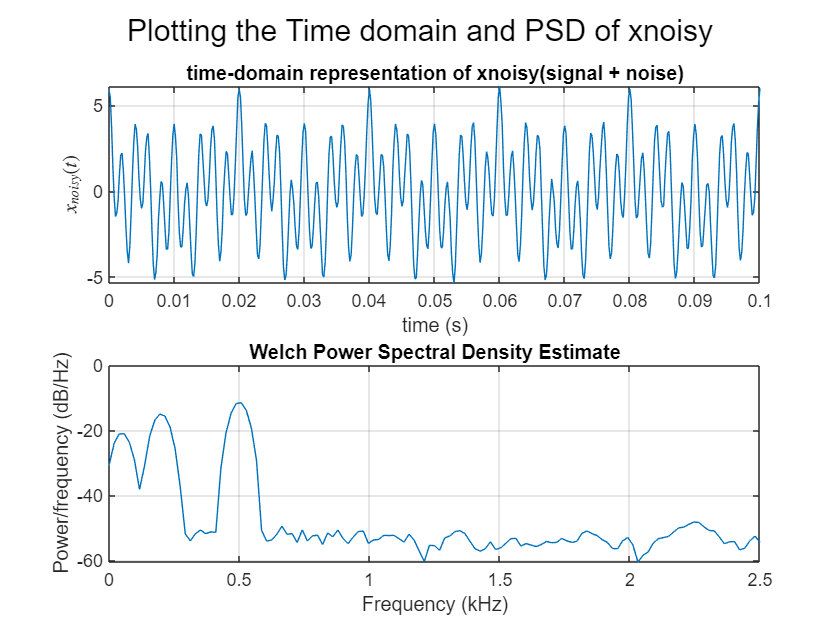

% Repeating above-steps but for noiseAmp = 0.1
noiseAmp = 0.1; 
noise = noiseAmp*randn(size(t)); % creating random gaussian (normal) signal of same duration (t) as x but amplified *0.1
xnoisy = x + noise; % Adding the two to create a noisy signal
figure
subplot(211); plot(t,xnoisy); % Shows time-domain representation of xnoisy
grid on 
xlabel('time (s)');
ylabel('$x_{noisy}(t)$', 'Interpreter', 'latex');
title('time-domain representation of xnoisy(signal + noise)');
subplot(212); pwelch(xnoisy,[],[],[],Fs) % Shows Power Spectral Density of xnoisy
sgtitle('Plotting the Time domain and PSD of xnoisy')

## **Exercise 10**

Record an audio signal using your PC's micophone. Then:

    **a) **Plot the time-domain representation of the signal and its power spectral (using `pwelch())`.

% script for part a)
clear
Fs = 44100; % defining the sampling rate for the signal to be recorded
noChannels = 1; % mono audio for simple manipulation
noBits = 8;
recorder = audiorecorder(Fs, noBits, noChannels); % Creates the recorder object with specified properties
get(recorder); % displays the properties of the object

       SampleRate: 44100
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'



disp('start speaking')

start speaking


recordblocking(recorder, 10); % Records 10 seconds of audio
disp('End of recording')

End of recording


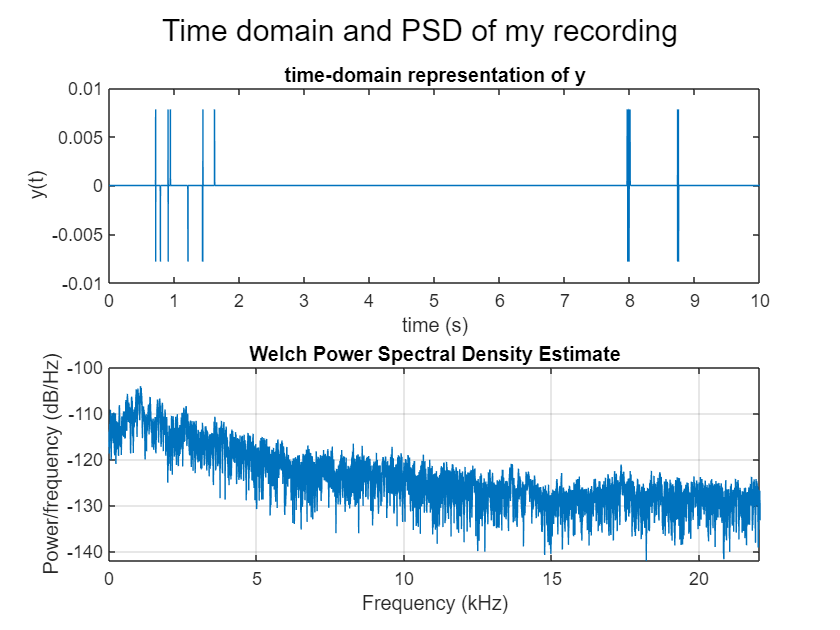

pause(3)
play(recorder); %Plays recording
y = getaudiodata(recorder); % Creates double-precision array
t = (0:length(y)-1)/Fs; % Creates time vector
figure;
subplot(211); plot(t,y);xlabel('time (s)'), ylabel('y(t)'), title('time-domain representation of y') % Creates time-domain representation
subplot(212); pwelch(y,[],[],[],Fs); % creates Power Spectral Density Estimate display
sgtitle('Time domain and PSD of my recording');

    **b) **Add a Guassian noise to the signal with `noiseAmp = 10` and `noiseAmp = 0.1 `and repeat part **a)**.

% script for part b)
noiseAmp = 10; 
noise = (noiseAmp*randn(size(t))); % creating random gaussian (normal) signal of same duration (t) as x but amplified *10
noise_colvec = noise'; % Converts the rowVector to a column vector to add to the y column vector
ynoisy = y + noise_colvec; % Adding the two to create a noisy signal
noiseAmp = 0.1; 
noise = noiseAmp*randn(size(t)); % a random Gaussian signal of the same length as y with amplification *.10
noise_colvec = noise';% Converts the rowVector to a column vector to add to the y column vector
ynoisy2 = y + noise_colvec; % generate samples of the noisy signal

    **c) **Find the PSD of the noisy signal generated in part **b)**.

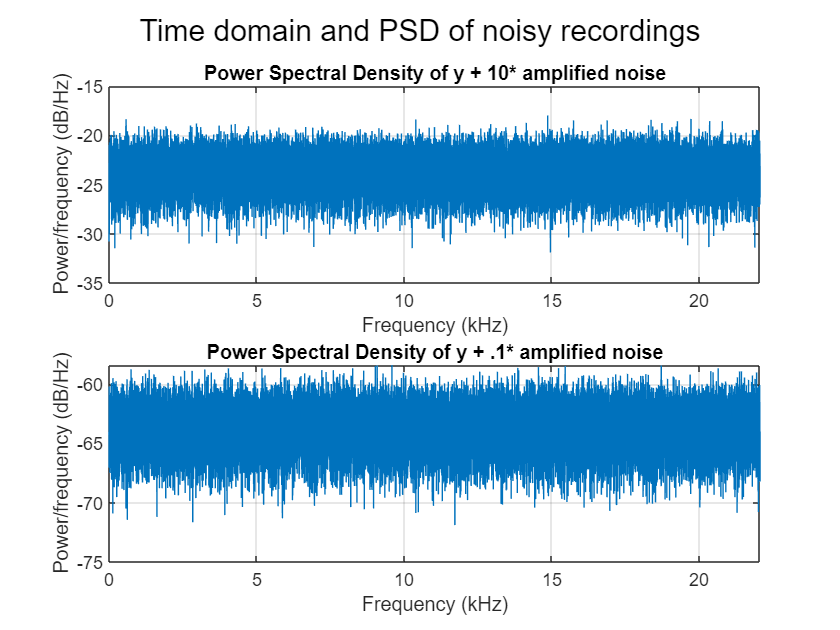

% script for part c)
figure;
subplot(211); pwelch(ynoisy,[],[],[],Fs), title('Power Spectral Density of y + 10* amplified noise')
subplot(212); pwelch(ynoisy2,[],[],[],Fs), title('Power Spectral Density of y + .1* amplified noise')
sgtitle('Time domain and PSD of noisy recordings');

    **d) **Find the spectrogram representations of the original signal and the noisy ones.

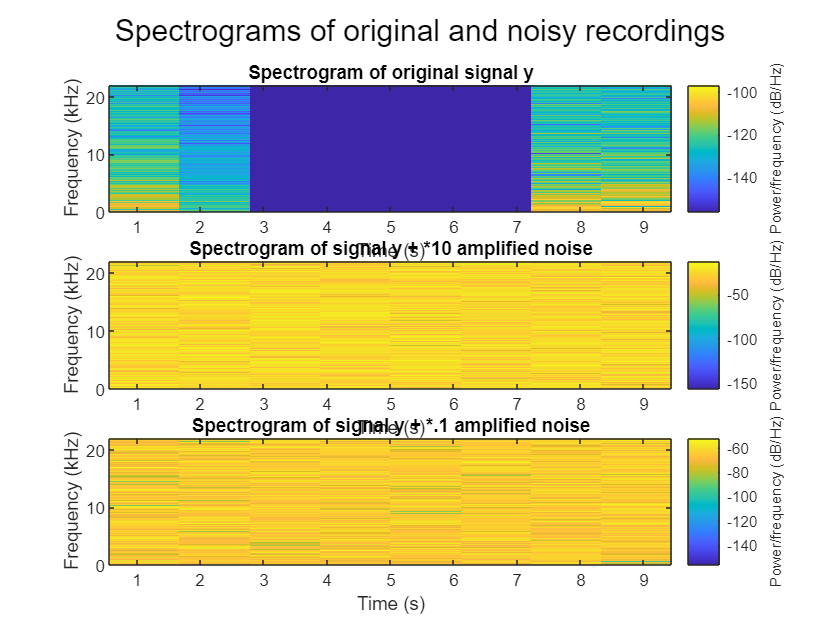

% script for part d)
figure;
subplot(311), spectrogram(y,[],[],[],Fs,'yaxis'), title('Spectrogram of original signal y'); % Original
subplot(312), spectrogram(ynoisy,[],[],[],Fs,'yaxis'), title('Spectrogram of signal y + *10 amplified noise'); %Amplified *10
subplot(313), spectrogram(ynoisy2,[],[],[],Fs,'yaxis'), title('Spectrogram of signal y + *.1 amplified noise'); %Amplified *.10
sgtitle('Spectrograms of original and noisy recordings');

## **Exercise 11**

Consider the following sinusoidal signal: 

$x{\left(t\right)}=\cos {\left(2\pi 100t\right)}+2\cos {\left(2\pi 400t\right)}+3\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi 700t\right)\;\;\;0\le t\le 0\ldotp 1\;s$      (1)

    **a) **Create samples of the signal $x{\left(t\right)}$ with the sampling rate of 7000 Hz. 

% script for part a)
clear
Fs = 7000; % Sampling rate 7000Hz
f1 = 100; % component 1
f2 = 400; % component 2
f3 = 700; % component 3
t = 0:1/Fs:0.1; % time vector
x_t = cos(2*pi*f1*t)+2.*cos(2*pi*f2*t)+3.*cos(2*pi*f3*t); % Creates samples of x(t) with 7Khz Fs

    **b) **Design a filter to let only the frequency component at 700 Hz pass. Plot the original and the filtered signals in the time-domain and then plot their spectrums.

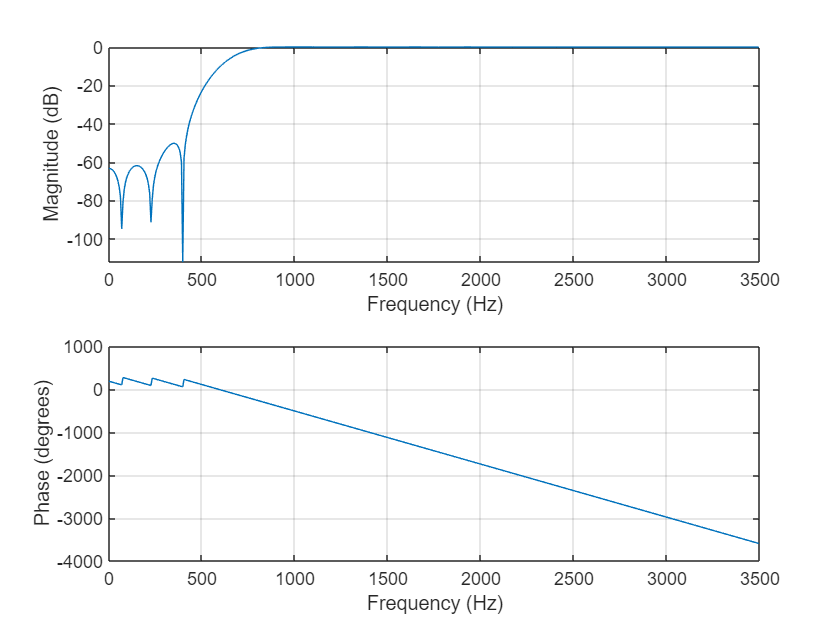

% script for part b)
n= 48; % 48th Order filter
Fc = 650; % cutoff everything below 650 frequency, passes higher frequencies
b_highpass = filtDesign(n,'high',Fc,Fs); % Creates a high pass-filter with the above properties

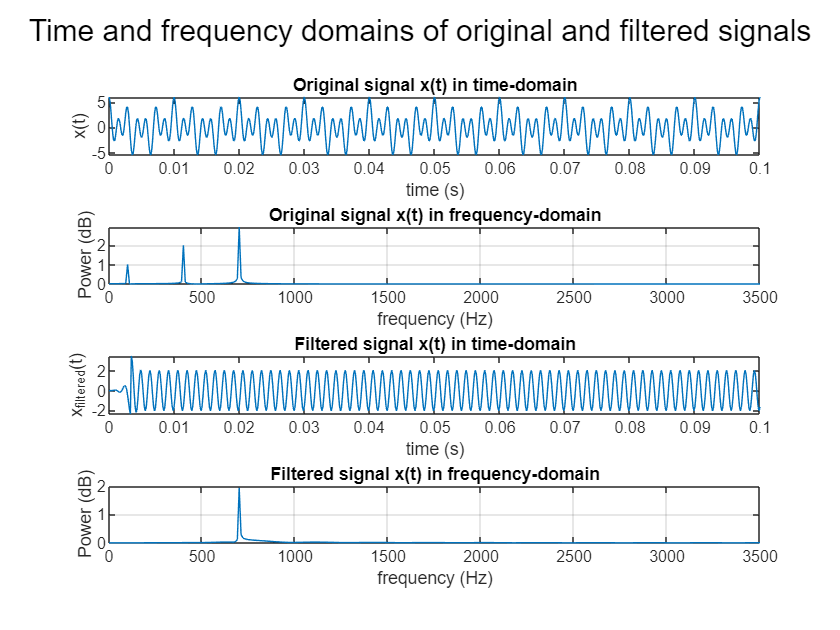

x_filtered = filter(b_highpass,1,x_t); % filters the original x signal with the filter we just created
figure
subplot(411); plot(t, x_t), xlabel ('time (s)'), ylabel('x(t)'), title('Original signal x(t) in time-domain');
subplot(412); plotSpectrum(x_t, Fs), ylabel('Power (dB)'), title('Original signal x(t) in frequency-domain');
subplot(413); plot(t, x_filtered), xlabel('time (s)'), ylabel('x_{filtered}(t)'), title('Filtered signal x(t) in time-domain');
subplot(414); plotSpectrum(x_filtered,Fs),ylabel('Power (dB)'),  title('Filtered signal x(t) in frequency-domain');
sgtitle('Time and frequency domains of original and filtered signals');

    **c) **Design a filter to let only the frequency component at 400 Hz pass. Plot the original and the filtered signals in the time-domain and then plot their spectrums.

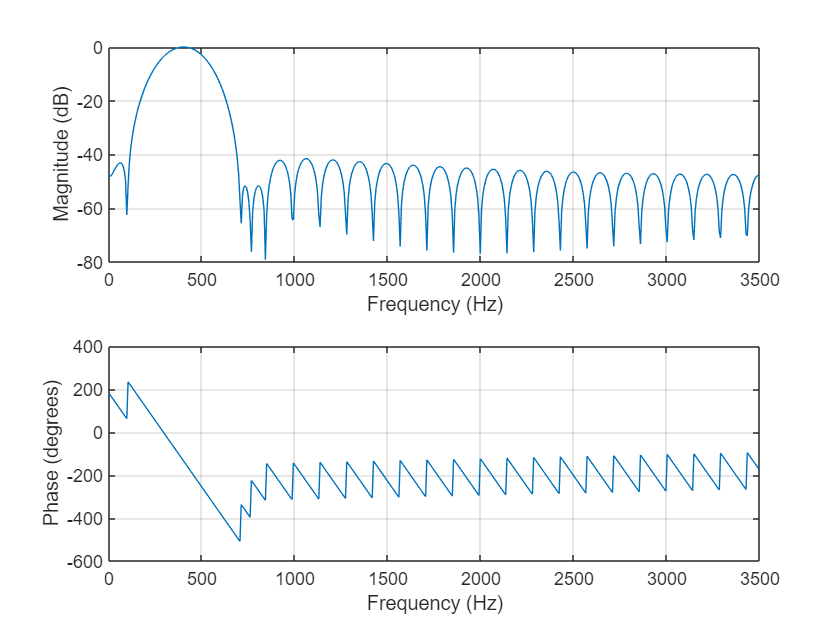

% script for part c)
Fc = [350 450]; % Creating bandpass frequency limits
b_bandpass = filtDesign(n, 'bandpass', Fc, Fs); % Creating a bandpass to only allow the 400 frequency component through, attenuating all else. 

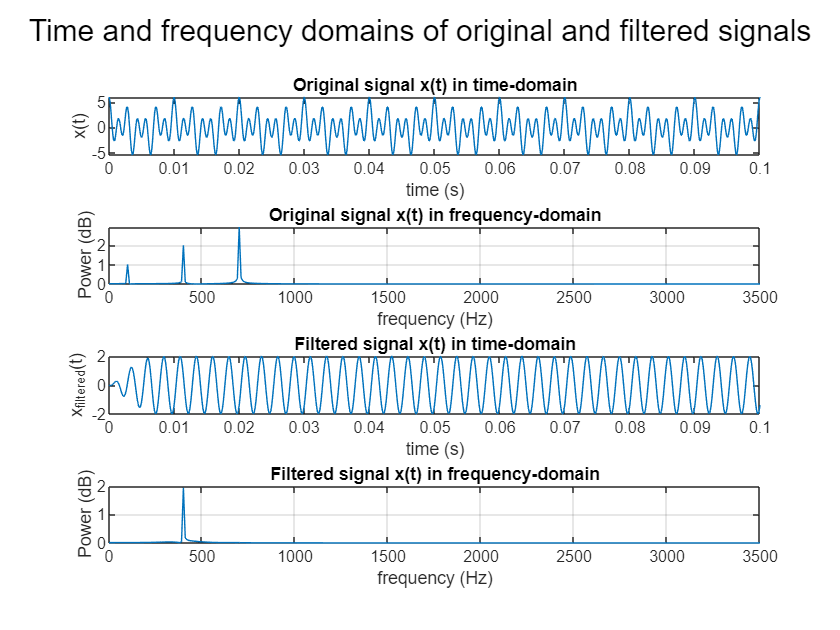

x_filtered = filter(b_bandpass,1,x_t); % filters the original x signal with the filter we just created
figure
subplot(411); plot(t, x_t), xlabel ('time (s)'), ylabel('x(t)'), title('Original signal x(t) in time-domain');
subplot(412); plotSpectrum(x_t, Fs), ylabel('Power (dB)'), title('Original signal x(t) in frequency-domain');
subplot(413); plot(t, x_filtered), xlabel('time (s)'), ylabel('x_{filtered}(t)'), title('Filtered signal x(t) in time-domain');
subplot(414); plotSpectrum(x_filtered,Fs),ylabel('Power (dB)'),  title('Filtered signal x(t) in frequency-domain'); % Allows only the 400Hz frequency component to pass
sgtitle('Time and frequency domains of original and filtered signals');

## **Exercise 12**

We want to apply a band-pass filter with lower and higher cut-off frequencies of 1000 to 2000 Hz to the audio signal in `testaudio.wav`.

    **a) **Design the filter and provide its frequency spectrum. Choose appropriate sampling rate for your filter.

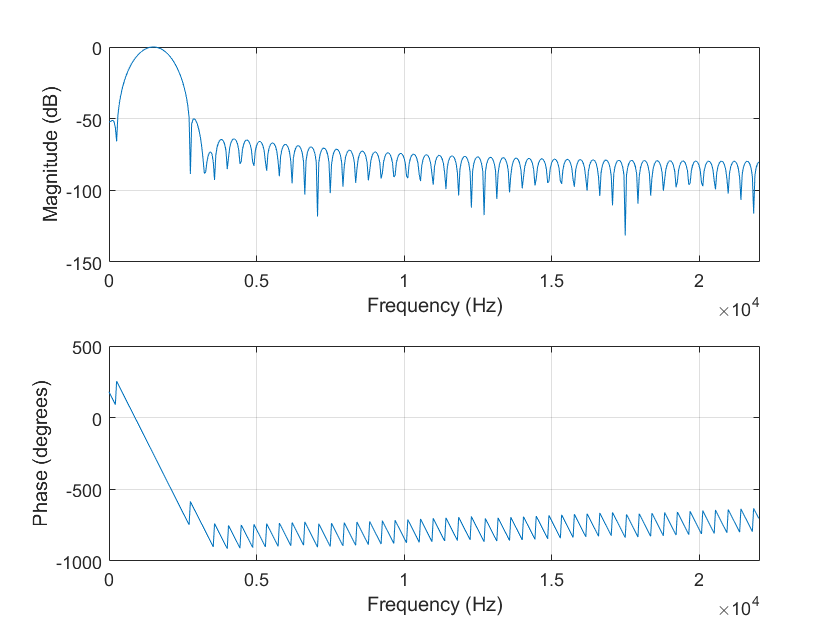

% script for part a)
clear
[y,Fs] = audioread('testaudio.wav'); %Fs = 441000
Fc = [1000 2000];
n = 100;
b_bandpass = filtDesign(n,'bandpass', Fc, Fs); 

    **b) **Apply the designed filter to the signal in `testaudio.wav` and plot the spectrum of the original and the filtered signals.

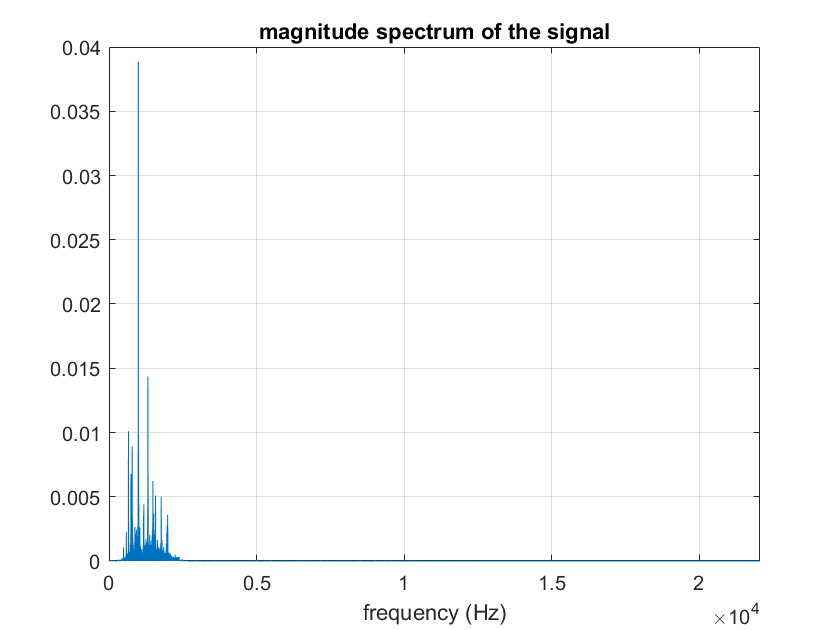

% script for part b)
y_filtered = filter(b_bandpass,1,y);
figure;
plotSpectrum(y_filtered, Fs);

    **c) **Play the original and the filtered signals.

% script for part c) 
soundsc(y,Fs);
pause(30); % signal duration 29.988s
soundsc(y_filtered,Fs);

## Exercise 13

    **a)** Create an audiorecorder object with a recording sampling rate of 44100 Hz, and record voice for 15 s.

    **b)** Play the recorded signal.

% script for parts a) and b)
% script for part a)
clear
Fs = 44100; % defining the sampling rate for the signal to be recorded
noChannels = 2; % to have stereo audio
noBits = 8;
recorder = audiorecorder(Fs, noBits, noChannels); % Creates recording object
get(recorder) % displays the properties of the object

       SampleRate: 44100
    BitsPerSample: 8
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'



disp('start speaking')

start speaking


recordblocking(recorder, 15);
disp('End of recording')

End of recording


play(recorder);

**    c) **Store data in double-precision array and plot the recorded signal as a function of time (in s).

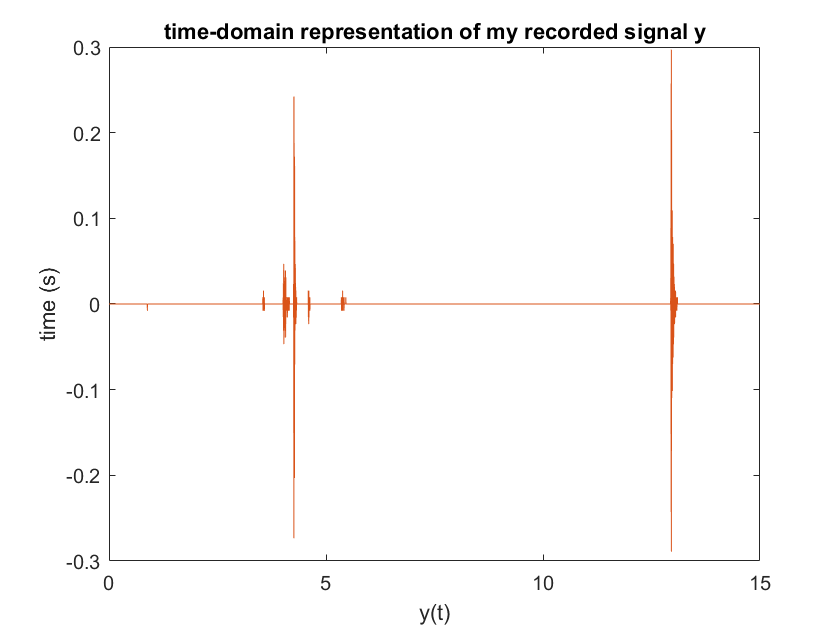

% script for parts c)
pause(15);
y = getaudiodata(recorder); % storing data in a double precision array
t = (0:length(y)-1)/Fs;
figure
plot(t,y); ylabel('time (s)'), xlabel('y(t)'), title('time-domain representation of my recorded signal y');

    **d)** Write the data as an audio file in `exercise13Recording.wav`.

% script for parts d)
audiowrite('excercise8Recording.wav', y, Fs);

    **e)** Downsample the recorded signal by 4 and 8, and play the new signals.

% script for parts e)
y_down4 = downsample(y,4);
soundsc(y_down4,Fs/4);
pause(15);
y_down8 = downsample(y,8);
soundsc(y_down8,Fs/8);

**    f) **Play the original recorded signal and the down-sampled versions as functions of time (in s).

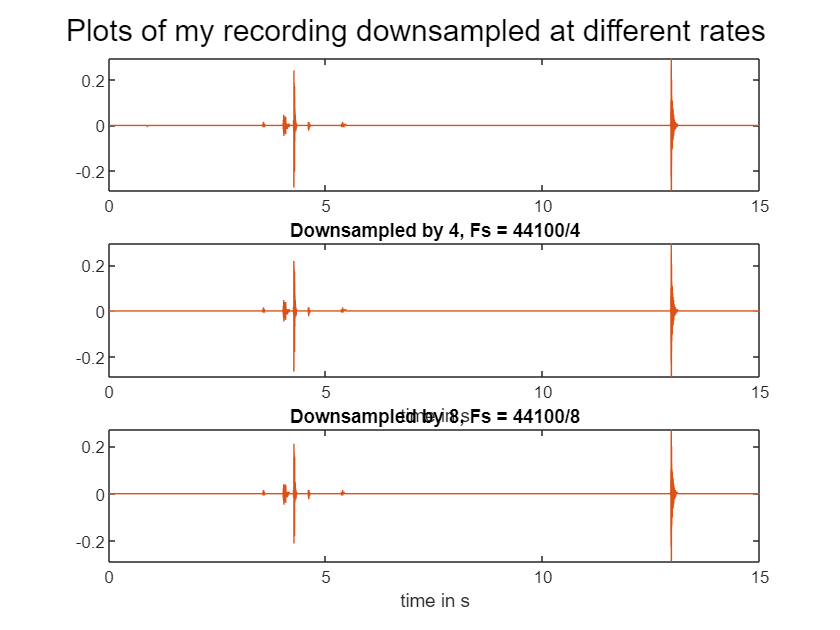

% script for parts e)
figure
subplot(311), plot(t,y)
t1 = (0:length(y_down4)-1)/(Fs/4); % New time vector to account for downsampling by 4
subplot(312), plot(t1,y_down4); xlabel('time in s') , title("Downsampled by 4, Fs = 44100/4");
t2 = (0:length(y_down8)-1)/(Fs/8); % New time vector to account for downsampling by 8
subplot(313), plot(t2,y_down8);  xlabel('time in s') , title("Downsampled by 8, Fs = 44100/8");
sgtitle('Plots of my recording downsampled at different rates ')

**    g) **Comment on parts e) and f) results. 

**    Your answer to part g)**: 

When downsampling by 4, the audio signal sounds very similar to the original signal, this is probably because the high sampling frequency (44100) provides a buffer against the effects of downsampling to an extent. The difference is much more evident when downsampled by 8, where the tone is clearly lower. 

## Exercise 14

The file `multiToneSignal.mat `contains samples of a multi-tone signal, i.e., a combination of a few sinusoids, with the sampling rate $f_s = 3$ KHz.

    **a)** Use `whos` to check variables saved in the file.

    **b)** Load the file and plot the signal as a function of time (in s).

% script for parts a) and b)
clear
whos -file multiToneSignal.mat

  Name                 Size                Bytes  Class     Attributes

  multiToneSignal      1x18003            144024  double              



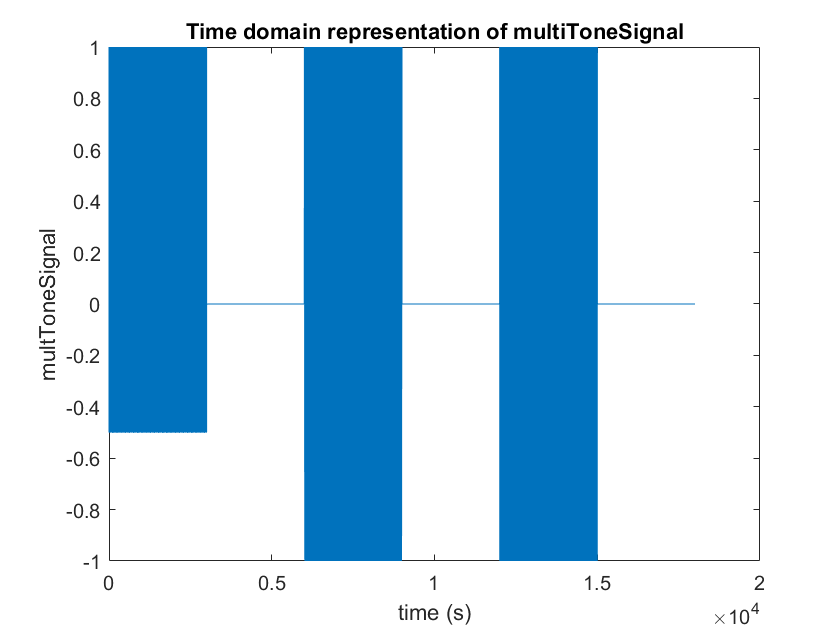

load multiToneSignal.mat
y = multiToneSignal;
Fs = 3000;
t = 0:length(y)-1/Fs;
figure;
plot(t,y); xlabel('time (s)'), ylabel('multToneSignal'),title('Time domain representation of multiToneSignal')

    **c)** Use `plotSpectrum()` to find the signal's spectrum. 

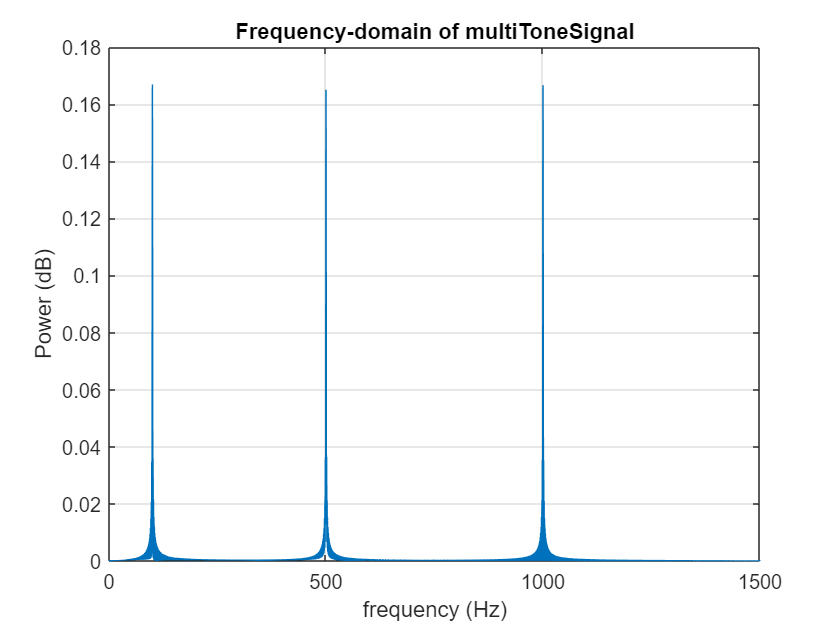

% script for part c)
figure;
plotSpectrum(y, Fs); ylabel('Power (dB)'); title('Frequency-domain of multiToneSignal');

    **d)** How many sinusoids are there in the signal and their frequencies.

    **Your answer to part d):**

There are three sinusoids in the signal, the first has frequency = 100, the second has frequency = 500, the third has frequency = 1000

    **e)** plot the Spectrogram of the signal. 

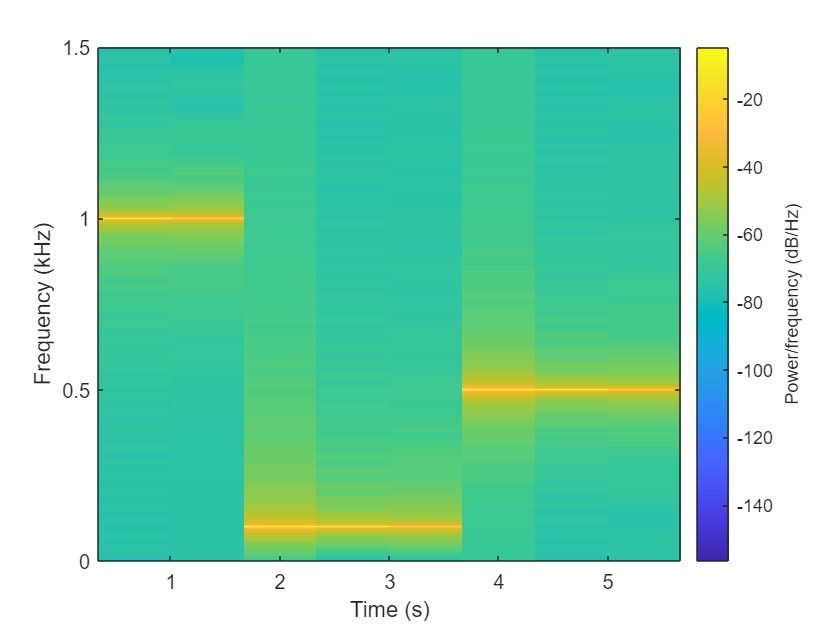

% script for part e)
spectrogram(y,[],[],[],Fs,'yaxis')

   ** f)** Determine the order of appearance of the frequency components.

    **Your answer to part f):**

The 1000 component frequency appears first, then the 100, then 500. 

## Exercise 15

    **a)** Load the audio signal `PinkPanther30.wav `and play it.

   ** b)** Plot the spectrum of the signal using the `plotSpectrum()` and find the fundamental frequency of the signal.

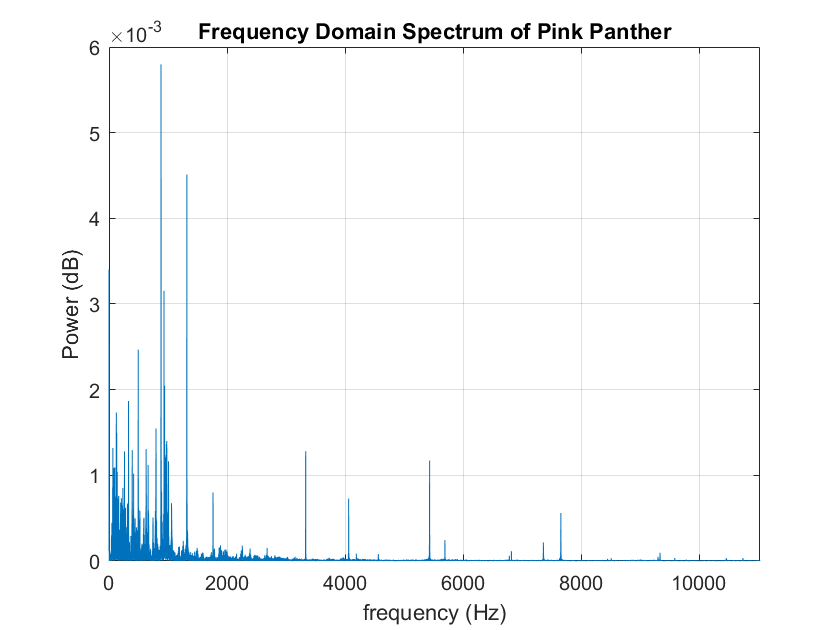

% scripts for parts a) and b)
clear
[y, Fs] = audioread("PinkPanther30.wav"); %loads audiosignal PinkPather30.wav
soundsc(y, Fs); % Plays the signal
pause(35); %signal duration 30 seconds, give 5 seconds for reading before playing adjusted signal.
% b)
T = length(y)/Fs; % duration of the signal in s
t = 0:1/Fs:T-1/Fs; % time samples 
figure
plotSpectrum(y,Fs), ylabel('Power (dB)'), title('Frequency Domain Spectrum of Pink Panther'); % plotting the Spectrum of Pink Panther

[Py , f] = pwelch(y,[],[],[],Fs); % Py is the PSD estimate of Pink Panther, f is it's corresponding frequency vector
[maxval,index] = max(Py); % this finds the max value (fundamental frequency) of Py, the Pink Panther Power spectrum, and its index
fundFreq = f(index); % this gives is the index of the fundamental frequency, the point at which Py peaks
disp(['the fundamental frequency of this signal is ', num2str(fundFreq)]) %display the fundamental frequency

the fundamental frequency of this signal is 880.8426


    **c)** Shift the fundamental frequency of the signal to 2 Kz.

    **d)** Play the frequency translated signal.

    **e)** Plot the spectrum of the frequency translated signal.

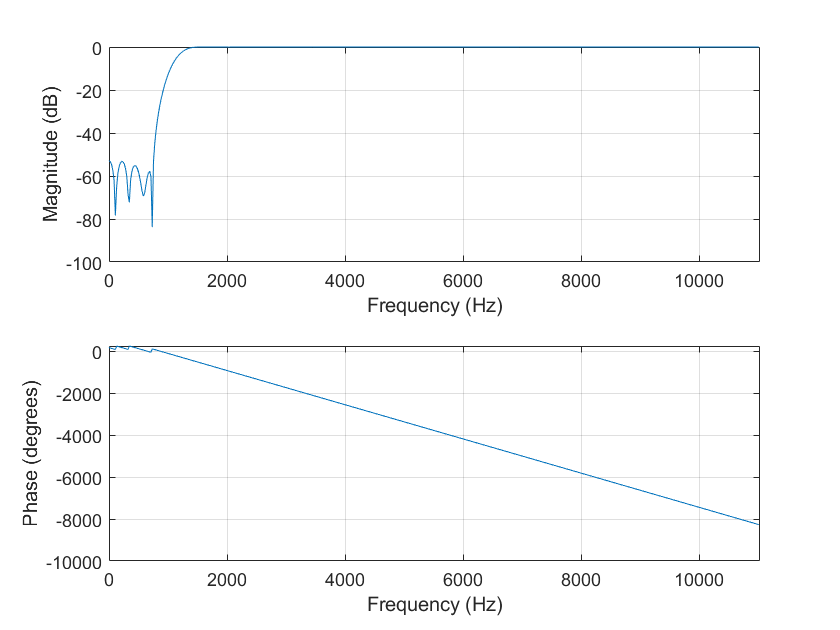

% scripts for parts c), d), and e)
% c)
% The current fundamental frequency is at 880 Hz, we want to shift it
% upward to 2000Hz
fc = 2000 - fundFreq;
carrier = cos(2*pi*fc*t); % generates the carrier
y_translated = y.*carrier'; % inverts the carrier to a column vector so it has same dimensions as y. Multiplies the signals and shift the fundfreq. 
b_highpass = filtDesign(100,'high',fc,Fs); % a filter that will attenuate components below the new fundamental frequency at 2Khz, ensuring that this is the lowest.

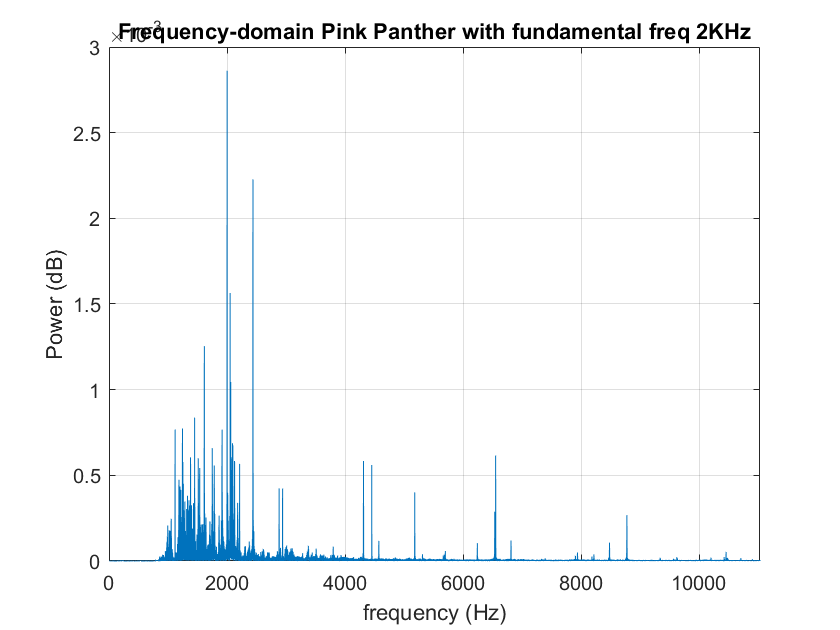

y_translated_filt = filter(b_highpass,1,y_translated); %Applying the filter
% d) 
soundsc(y_translated_filt, Fs) % plays the new signal
% e)
plotSpectrum(y_translated_filt,Fs), ylabel('Power (dB)'),title('Frequency-domain Pink Panther with fundamental freq 2KHz'); % plotting the Spectrum of Pink Panther